% solution to van der Pol equation

type vander_func.m


function [ds] = vander_func(s, t, param)
% van der Pol equation of state s and time t
% returns ds, where ds/dt = f(s, t)
% get state variables from s
x = s(1);
y = s(2);
% find derivatives of state variables
dy = x;
dx = -y + (1-y^2)*x;
ds = [dx dy]';
end


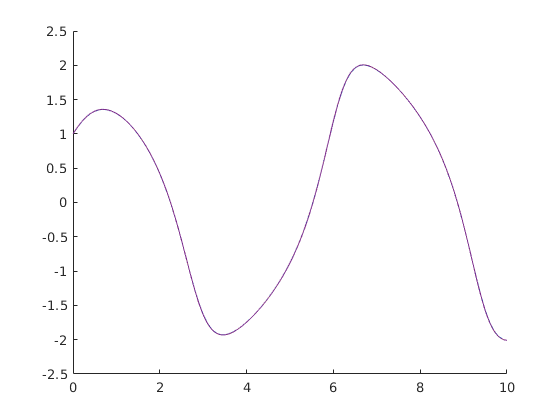


tau = [0.1, 0.01, 0.001, 0.0001];

hold on
for i = 1:length(tau)
    nstep = 10 / tau(i); % steps needed to solve
    state = [1, 1]';
    t = 0;
    yplot = zeros(1, nstep);
    tplot = zeros(1, nstep);
    for j = 1:nstep
        % add values to 
        yplot(j) = state(2);
        tplot(j) = t;
        state = rk4(state, time, tau(i), 'vander_func', []);
        y = state(2);
        t = t + tau(i);
    end
    plot(tplot, yplot)
end
hold off